# Airfoil Morphing Tool 

clear;close all;clc

## Import the airfoil coordinates

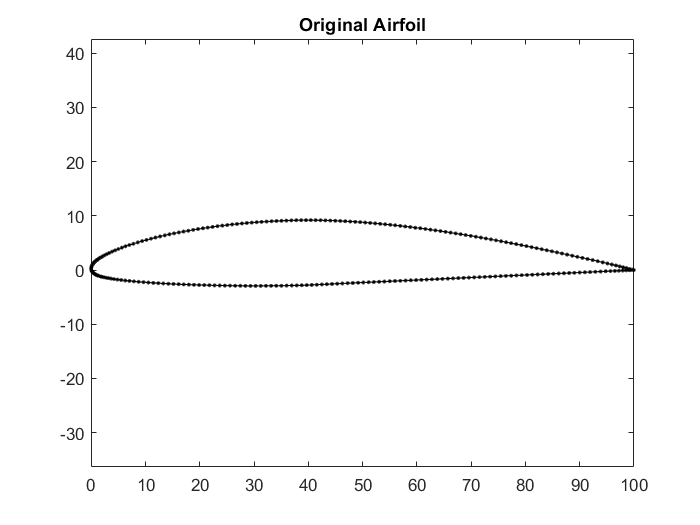

FileName = '64A612.dat';
data = ReadAirfoil(FileName);

%Plot the original airfoil
plot(data.xy(1,:),data.xy(2,:),'k.-'); 
title('Original Airfoil'); axis equal;

## Collect Input Data

Give the input data

### Slat Data

data.slat.XPercent = 30;
data.slat.YPercent = 50;
data.slat.Angle = 20;


### Flap Data

data.flap.XPercent = 60;
data.flap.YPercent = 50;
data.flap.Angle = 20;

Select the type of modification needed for the flap.

data.Contour = "C";
data.Modification = "Both";

The below code runs only if Modification is Mixed.

Mixed could be used for corrugated airfoil models where a section of airfoil is continuous and the rest is rigid. This however may not be accurate due to absence of Material effect and FEM calculation. This section is only for Visualization of such an effect.

Enter the X location where the corrugation ends. 

Make sure you give the X of corrugation start in "Flap Data"

if data.Contour == "M"
    data.flap.XcPercent = 70;
else
    data.Contour = data.Contour;
end

## Pre processing

Removing repeating co-ordinates

data.xyu = unique(data.xy','rows','stable')';

Ensuring the last point isn not removed

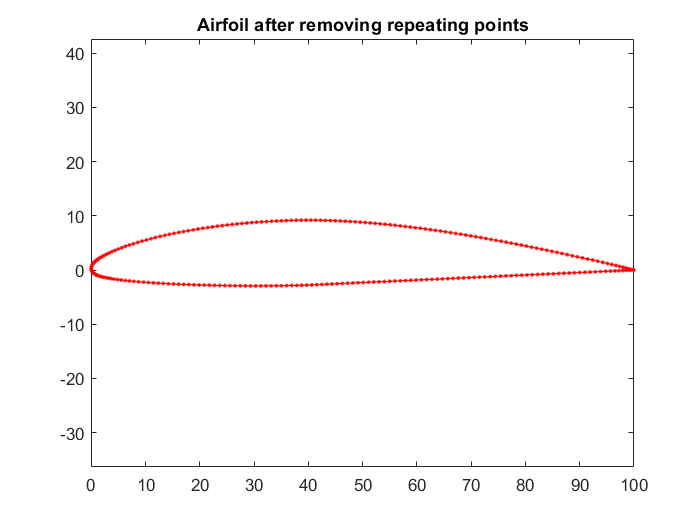

if isequal(data.xy(:,1),data.xy(:,end))
    data.xyu(:,end+1) = data.xyu(:,1);
end
plot(data.xyu(1,:),data.xyu(2,:),'r.-'); 
title ("Airfoil after removing repeating points"); axis equal;

### Thickness Camber Function

Get all X and Y values as separate data

data.xall1 = data.xyu(1,:);
data.yall1 = data.xyu(2,:);

Get the indices of points in upper surface and lower surface separately

TopNos=1:min(find(data.xall1==min(data.xall1)));
BotNos=min(find(data.xall1==min(data.xall1))):length(data.xall1);

Get the top and bottom surface co-ordinates of the airfoil

%Top Surface
data.xy_top = data.xyu(:,TopNos);
data.xtop=data.xall1(TopNos); data.ytop=data.yall1(TopNos);

%Bottom Surface
data.xy_bot = data.xyu(:,BotNos);
data.xbot=data.xall1(BotNos); data.ybot=data.yall1(BotNos);

Get the trailing edge angles

theta1 = atan2(data.ytop(2)-data.ytop(1),data.xtop(2)-data.xtop(1));
if theta1<0
    theta1=theta1+2*pi;
end
theta2 = atan2(data.ybot(end-1)-data.ybot(end),data.xbot(end-1)-data.xbot(end));
if theta2<0
    theta2=theta2+2*pi;
end
data.TE_Angle = (theta2-theta1)*180/pi; %in Degrees
data.TE_Thick = abs(data.xyu(2,1)-data.xyu(2,end));

Fitting through spline

data.X1 = linspace(min( min(data.xtop), min(data.xbot) ), max( max(data.xtop), max(data.xbot) ),20);
data.Y1 = spline(data.xtop,data.ytop,data.X1);
data.Y2 = spline(data.xbot,data.ybot,data.X1);

Finding the thickness distribution

data.ThickDistr= data.Y1-data.Y2;
data.MaxThickY = max(data.ThickDistr);
data.MaxThickX = data.X1(data.ThickDistr==data.MaxThickY);

Finding camber distribution

data.CamberDistr=(data.Y1+data.Y2)/2;
data.MaxCamberY = max(data.CamberDistr);
data.MaxCamberX = data.X1(data.CamberDistr==data.MaxCamberY);

## Set Slat Flap

%SLAT
if data.Modification == "Slat"       
    if abs(data.slat.Angle) > 0
            %GET FINAL COORDINATE
            [data.transformed,data.transformed_topxy,data.transformed_botxy] = Slat(data);
     else
        data.transformed = data.xyu;
        data.transformed_topxy = data.xy_top;
        data.transformed_botxy = data.xy_bot;
    end
end

%FLAP
if data.Modification == "Flap"
    if abs(data.flap.Angle *-1) > 0
        [data.transformed,data.transformed_topxy,data.transformed_botxy] = Flap(data);
    else
       data.transformed = data.xyu;
       data.transformed_topxy = data.xy_top;
       data.transformed_botxy = data.xy_bot;
    end        
end

if data.Modification == "Both"
    %SLAT
    if abs(data.slat.Angle) > 0
       [slat,slatTop,slatBot] = Slat(data);
     else
        slat = data.xyu;
        slatTop = data.xy_top;
        slatBot = data.xy_bot;
    end
    
    %FLAP
    if abs(data.flap.Angle *-1) > 0
        [flap,flapTop,flapBot] = Flap(data);
        
        %Get Final Coords
        topsurf = InterX(slatTop,flapTop);
        botsurf = InterX(flapBot,slatBot);
        data.transformed_topxy = [flapTop(:,1:max(find(flapTop(1,:) > topsurf(1)))) slatTop(:,min(find(slatTop(1,:) < topsurf(1))):length(slatTop))];
        data.transformed_botxy = [slatBot(:,1:max(find(slatBot(1,:) < botsurf(1)))) flapBot(:,min(find(flapBot(1,:) > botsurf(1))):length(flapBot))];
        data.transformed = [data.transformed_topxy data.transformed_botxy];
    else
        data.transformed = slat;
        data.transformed_topxy = slatTop;
        data.transformed_botxy = slatBot;
    end
end

## Finishing up 

The below code is used to plot the original airfoil and morphed airfoil

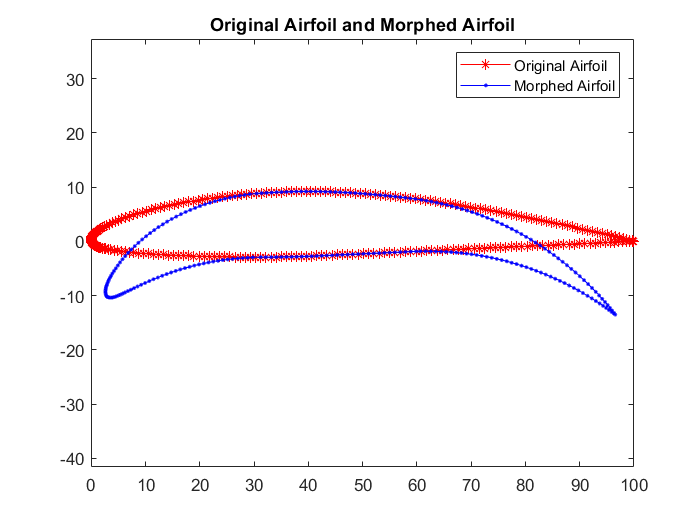

data.transformed = unique(data.transformed','rows','stable')';
plot(data.xyu(1,:),data.xyu(2,:),'r*-'); axis equal; hold on;
plot(data.transformed(1,:),data.transformed(2,:),'b.-');axis equal;hold off
title('Original Airfoil and Morphed Airfoil');
legend('Original Airfoil','Morphed Airfoil');

The below code is used to export the airfoil into a **.dat** file

fileID = fopen('AIRFOIL_MOD.DAT','w');
fprintf(fileID,'%s:SLAT_%2.1f(%2.1f,%2.1f),FLAP_%2.1f(%2.1f,%2.1f)\n',...
    data.afname{1},data.slat.Angle,data.slat.XPercent,data.slat.YPercent,...
    data.flap.Angle,data.flap.XPercent,data.flap.YPercent);
fprintf(fileID,'%3.5f %3.5f\n',data.transformed/100);
fclose(fileID);

## Functions

function data = ReadAirfoil(FileName)
% Function to read airfoil from file
% FileName = '2412.dat';
fid = fopen(FileName, 'r');
% Read coordinates (starting from trailing edge, going anticlockwise on upper side and finishing with trailing edge 
data.xy = (cell2mat(textscan(fid, '%f %f','headerlines', 1))*100)';
data.afname=textread(FileName,'%s',1,'delimiter','\n');
end

function Morphcoord = Morph(xy,angle,hinge,Order)
theta = angle;
if Order == 1
 % Rotation Matrix
        R = [cosd(theta) -sind(theta); sind(theta) cosd(theta)];
        % Rotational Axis
        center_of_rotation1 = repmat(hinge, 1, length(xy));
        % Transforming Origin
        xy_shifted = (xy - center_of_rotation1);
        % Performing Rotation
        xy_rotated = (R * xy_shifted);
        % Reverse Transform
        Morphcoord = xy_rotated + center_of_rotation1;
elseif Order == 2
        center_of_rotationM = repmat(hinge, 1, length(xy));
        %Getting distance between the hinge point and 
        dist = sqrt((xy(1,:)-center_of_rotationM(1,:)).^2+(xy(2,:)-center_of_rotationM(2,:)).^2);
        distNorm = dist./max(dist);
        for i1 = 1:length(xy)
            p=xy(:,i1);
            theta = angle*distNorm(i1);
            % Rotation Matrix
            R = [cosd(theta) -sind(theta); sind(theta) cosd(theta)];
            % Transforming Origin
            xy_shifted = (p - hinge);
            % Performing Rotation
            xy_rotated = (R * xy_shifted);
            % Reverse Transform
            xy_new1 = xy_rotated + hinge;
            Morphcoord(:,i1)=xy_new1;     
        end
end
end

function [Slat, Slat_top, Slat_bot] = Slat(data)

    data.slat.LocalThickness = interp1(data.X1,data.ThickDistr,data.slat.XPercent);
    data.slat.LocalCamber= interp1(data.X1,data.CamberDistr,data.slat.XPercent);
    data.slat.XHinge = data.slat.XPercent;
    data.slat.YHinge = data.slat.LocalThickness * data.slat.YPercent/100 -(data.slat.LocalThickness/2-data.slat.LocalCamber);
    thetas = data.slat.Angle;
    center_of_rotation = [data.slat.XHinge;data.slat.YHinge];
    %Top Surface
    TopNosSlat = min(find(data.xtop<data.slat.XHinge)):length(data.xtop);
    xtopS = data.xtop(TopNosSlat); ytopS = data.ytop(TopNosSlat);
    data.slat.topxy = [xtopS; ytopS];
    %Bottom Surface
    BotNosSlat=min(find(data.xbot)):max(find(data.xbot<data.slat.XHinge));
    xbotS = data.xbot(:,BotNosSlat); ybotS = data.ybot(:,BotNosSlat);
    data.slat.botxy = [xbotS; ybotS];
    
        if data.Contour == "H"
            %Top Surface
            slattop = Morph(data.slat.topxy,thetas,center_of_rotation,1);
            coord_top = [data.xy_top(:,1:TopNosSlat) slattop];
            
            %Bottom Surface
            slatbot = Morph(data.slat.botxy,thetas,center_of_rotation,1);
            coord_bot = [slatbot(:,1:length(slatbot)-1) data.xy_bot(:,length(xbotS)+3:length(data.xy_bot))]; %data.xyu(:,1)
           
        elseif data.Contour == "C"
            %Top Surface
            slattopC = Morph(data.slat.topxy,thetas,center_of_rotation,2);
            STnewXYs = [data.xy_top(:,1:TopNosSlat-1) slattopC];
            
            Pt = InterX(data.xy_top,STnewXYs);
            Pt1 = [Pt(1,1); Pt(2,1)];
            ind1 = find(data.xy_top(1,:)>Pt(1),1,'last') ; % find coordinate before intersection
            ind2 = find(STnewXYs(1,:)<Pt(1),1); % find coordinate after intersection
            coord_top = [data.xy_top(:,1:ind1) Pt1 STnewXYs(:,ind2:end)];            
            
            %Bottom Surface
            slatbotC = Morph(data.slat.botxy,thetas,center_of_rotation,2);
            SBnewXYs = [slatbotC data.xy_bot(:,length(xbotS)+2:length(data.xy_bot)) ]; %STnewXYs(:,min(find(STnewXYs)))
            
            Pb = InterX(data.xy_bot,SBnewXYs);
            Pb1 = [Pb(1,1); Pb(2,1)];
            ind1 = find(SBnewXYs(1,:)<Pb(1),1,'last') ; % find coordinate before intersection
            ind2 = find(data.xy_bot(1,:)>Pb(1),1); % find coordinate after intersection
            coord_bot = [SBnewXYs(:,1:ind1) Pb1 data.xy_bot(:,ind2:end)];
        
        elseif data.Contour == "M"
                        
        end
    
        %GET FINAL COORDINATE
        Slat = [coord_top coord_bot];
        Slat_top = coord_top;
        Slat_bot = coord_bot;
end

function [Flap, Flap_top, Flap_bot] = Flap(data)
    data.flap.LocalThickness = interp1(data.X1,data.ThickDistr,data.flap.XPercent);
    data.flap.LocalCamber= interp1(data.X1,data.CamberDistr,data.flap.XPercent);
    data.flap.XHinge = data.flap.XPercent;
    %data.flap.XcHinge = data.flap.XcPercent;
    data.flap.YHinge = data.flap.LocalThickness * data.flap.YPercent/100 -(data.flap.LocalThickness/2-data.flap.LocalCamber);
    thetaf = data.flap.Angle *-1;
    center_of_rotation = [data.flap.XHinge;data.flap.YHinge];
    %Top Surface
    TopNosFlap = 1:min(find(data.xtop<data.flap.XHinge));
    xtopF = data.xtop(TopNosFlap); ytopF = data.ytop(TopNosFlap);
    data.flap.topxy = [xtopF; ytopF];
    %Bottom Surface
    BotNosFlap= min(find(data.xbot>data.flap.XHinge)):max(find(data.xbot));
    xbotF = data.xbot(:,BotNosFlap); ybotF = data.ybot(:,BotNosFlap);
    data.flap.botxy = [xbotF; ybotF];
    if data.Contour == "H"
            %Top Surface
            flaptop = Morph(data.flap.topxy,thetaf,center_of_rotation,1);
            coord_top = [flaptop(:,1:length(flaptop)-1) data.xy_top(:,max(TopNosFlap)+1:length(data.xy_top))];
        
            %Bottom Surface
            flapbot = Morph(data.flap.botxy,thetaf,center_of_rotation,1);
            coord_bot = [data.xy_bot(:,min(find(data.xy_bot)):min(BotNosFlap)-2) flapbot(:,min(find(flapbot))+1:length(flapbot)) ]; %coord_top(:,min(find(coord_top)))
    
    elseif data.Contour == "C"
            %Top Surface
            flaptopC = Morph(data.flap.topxy,thetaf,center_of_rotation,2);
            FTnewXYf = [flaptopC(:,1:length(flaptopC)-1) data.xy_top(:,max(TopNosFlap):length(data.xy_top))];
           
            Pt = InterX(data.xy_top,FTnewXYf);
            Pt1 = [Pt(1,1); Pt(2,1)];
            ind1 = find(FTnewXYf(1,:)>Pt(1),1,'last') ; % find coordinate before intersection
            ind2 = find(data.xy_top(1,:)<Pt(1),1); % find coordinate after intersection
            coord_top = [FTnewXYf(:,1:ind1) Pt1 data.xy_top(:,ind2:end)];
            
            %Bottom Surface
            flapbotC = Morph(data.flap.botxy,thetaf,center_of_rotation,2);
            FBnewXYf = [data.xy_bot(:,min(find(data.xy_bot)):min(BotNosFlap)-1) flapbotC ]; %FTnewXYf(:,min(find(FTnewXYf)))
        
            Pb = InterX(data.xy_bot,FBnewXYf);
            Pb1 = [Pb(1,1); Pb(2,1)];
            ind1 = find(data.xy_bot(1,:)<Pb(1),1,'last') ; % find coordinate before intersection
            ind2 = find(FBnewXYf(1,:)>Pb(1),1); % find coordinate after intersection
            coord_bot = [data.xy_bot(:,1:ind1) Pb1 FBnewXYf(:,ind2:end)];
    
    elseif data.Contour =="M"
            %Top Surface HINGED
            flaptop = Morph(data.flap.topxy,thetaf,center_of_rotation,1);
            coord_top = [flaptop(:,1:length(flaptop)-1) data.xy_top(:,max(TopNosFlap)+1:length(data.xy_top))];
            
            %Bottom Surface HINGED
            flapbot = Morph(data.flap.botxy,thetaf,center_of_rotation,1);
            coord_bot = [data.xy_bot(:,min(find(data.xy_bot)):min(BotNosFlap)-2) flapbot(:,min(find(flapbot))+1:length(flapbot)) ]; %coord_top(:,min(find(coord_top)))
    
    end
    %GET FINAL COORDINATE
    Flap = [coord_top coord_bot];
    Flap_top = coord_top;
    Flap_bot = coord_bot;
end